% MECH 6318 - HW 2
% Jonas Wagner
% 2021-09-07

clear
close all


## Problem 11.3

f = @(x) 8*x(1,:,:) + 10*x(2,:,:) + 4

f = function_handle with value:
    @(x)8*x(1,:,:)+10*x(2,:,:)+4



A = [-1,-1;
     1, 1]

A =     -1    -1
     1     1


b = [4;
     6]

b =      4
     6



LB = [0;
     0]

LB =      0
     0


UB = []


UB =

     []




% Plot F(x)
lb = 0;
ub = 6;
[X1,X2] = meshgrid(lb:0.1:ub, lb:0.1:ub);%3.5:0.1:6,0:0.1:2);
F = 8*X1 + 10*X2 + 4

F =     4.0000    4.8000    5.6000    6.4000    7.2000    8.0000    8.8000    9.6000   10.4000   11.2000   12.0000   12.8000   13.6000   14.4000   15.2000   16.0000   16.8000   17.6000   18.4000   19.2000   20.0000   20.8000   21.6000   22.4000   23.2000   24.0000   24.8000   25.6000   26.4000   27.2000   28.0000   28.8000   29.6000   30.4000   31.2000   32.0000   32.8000   33.6000   34.4000   35.2000   36.0000   36.8000   37.6000   38.4000   39.2000   40.0000   40.8000   41.6000   42.4000   43.2000
    5.0000    5.8000    6.6000    7.4000    8.2000    9.0000    9.8000   10.6000   11.4000   12.2000   13.0000   13.8000   14.6000   15.4000   16.2000   17.0000   17.8000   18.6000   19.4000   20.2000   21.0000   21.8000   22.6000   23.4000   24.2000   25.0000   25.8000   26.6000   27.4000   28.2000   29.0000   29.8000   30.6000   31.4000   32.2000   33.0000   33.8000   34.6000   35.4000   36.2000   37.0000   37.8000   38.6000   39.4000   40.2000   41.0000   41.8000   42.6000   43.4000   44

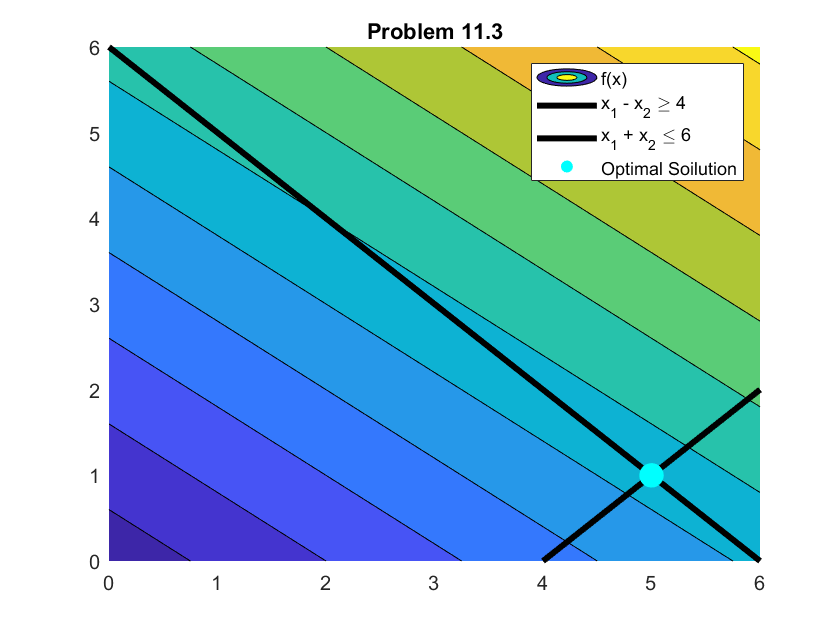


figure()
hold on
contourf(X1, X2, F, 'DisplayName', 'f(x)')
fimplicit(@(x1,x2) x1 - x2 - 4, [lb,ub], ...
    'k', 'LineWidth', 3, ...
    'DisplayName', 'x_1 - x_2 \geq 4')
fimplicit(@(x1,x2) x1 + x2 - 6, [lb,ub], ...
    'k', 'LineWidth', 3, ...
    'DisplayName', 'x_1 + x_2 \leq 6')
scatter(5,1, 150, 'filled', 'c',...
    'DisplayName', 'Optimal Soilution')
legend
title('Problem 11.3')

## Problem 11.4

F = [1;
     5;
     3]

F =      1
     5
     3



A = [-1, 5, -3;
      5, 1, 2;
     -2, 1, 2;
      3, 8, 3]

A =     -1     5    -3
     5     1     2
    -2     1     2
     3     8     3


b = [-1;
      5;
      4;
      3]

b =     -1
     5
     4
     3



LB = [0; 0; -inf]

LB =      0
     0
  -Inf


UB = []


UB =

     []



## Problem 11.5

A = [1, 2, 2, 0;
     1, 1, 1 -1;
     0, 3, 1, 2]

A =      1     2     2     0
     1     1     1    -1
     0     3     1     2


b = [4;
     1;
     6]

b =      4
     1
     6



% Part a
n = size(A,1)

n = 3

m = rank(A)

m = 3

max_basic_sol = nchoosek(n,m)

max_basic_sol = 1


% Part b
rref_11_5 = rref([A,b])

rref_11_5 =     1.0000         0         0   -2.0000   -2.0000
         0    1.0000         0    0.5000    1.5000
         0         0    1.0000    0.5000    1.5000


## Problem 11.7

c = [1;
    -2]

c =      1
    -2



A = [-4, 6;
      1, 1]

A =     -4     6
     1     1


b = [9;
     4]

b =      9
     4





syms f
T = [[A,eye(2),b];[c',zeros(1,2),f]]

$$T = \left(\begin{array}{ccccc} -4 & 6 & 1 & 0 & 9\\ 1 & 1 & 0 & 1 & 4\\ 1 & -2 & 0 & 0 & f \end{array}\right)$$


R1 = T(1,:)

$$R1 = \left(\begin{array}{ccccc} -4 & 6 & 1 & 0 & 9 \end{array}\right)$$

R2 = T(2,:)

$$R2 = \left(\begin{array}{ccccc} 1 & 1 & 0 & 1 & 4 \end{array}\right)$$

R3 = T(3,:)

$$R3 = \left(\begin{array}{ccccc} 1 & -2 & 0 & 0 & f \end{array}\right)$$


R1 = R1/6

$$R1 = \left(\begin{array}{ccccc} -\frac{2}{3} & 1 & \frac{1}{6} & 0 & \frac{3}{2} \end{array}\right)$$

T = [R1;R2;R3]

$$T = \left(\begin{array}{ccccc} -\frac{2}{3} & 1 & \frac{1}{6} & 0 & \frac{3}{2}\\ 1 & 1 & 0 & 1 & 4\\ 1 & -2 & 0 & 0 & f \end{array}\right)$$


R2 = (3/5)*(R2 - R1)

$$R2 = \left(\begin{array}{ccccc} 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2} \end{array}\right)$$

T = [R1;R2;R3]

$$T = \left(\begin{array}{ccccc} -\frac{2}{3} & 1 & \frac{1}{6} & 0 & \frac{3}{2}\\ 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2}\\ 1 & -2 & 0 & 0 & f \end{array}\right)$$


R1 = R1 + (2/3)*R2

$$R1 = \left(\begin{array}{ccccc} 0 & 1 & \frac{1}{10} & \frac{2}{5} & \frac{5}{2} \end{array}\right)$$

T = [R1;R2;R3]

$$T = \left(\begin{array}{ccccc} 0 & 1 & \frac{1}{10} & \frac{2}{5} & \frac{5}{2}\\ 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2}\\ 1 & -2 & 0 & 0 & f \end{array}\right)$$


R3 = R3 + 2*R1

$$R3 = \left(\begin{array}{ccccc} 1 & 0 & \frac{1}{5} & \frac{4}{5} & f+5 \end{array}\right)$$

T = [R1;R2;R3]

$$T = \left(\begin{array}{ccccc} 0 & 1 & \frac{1}{10} & \frac{2}{5} & \frac{5}{2}\\ 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2}\\ 1 & 0 & \frac{1}{5} & \frac{4}{5} & f+5 \end{array}\right)$$


R3 = R3 - R2

$$R3 = \left(\begin{array}{ccccc} 0 & 0 & \frac{3}{10} & \frac{1}{5} & f+\frac{7}{2} \end{array}\right)$$

T = [R1;R2;R3]

$$T = \left(\begin{array}{ccccc} 0 & 1 & \frac{1}{10} & \frac{2}{5} & \frac{5}{2}\\ 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2}\\ 0 & 0 & \frac{3}{10} & \frac{1}{5} & f+\frac{7}{2} \end{array}\right)$$


final_simplex_tbl = [T(2,:);T(1,:);T(3,:)]

$$final\_simplex\_tbl = \left(\begin{array}{ccccc} 1 & 0 & -\frac{1}{10} & \frac{3}{5} & \frac{3}{2}\\ 0 & 1 & \frac{1}{10} & \frac{2}{5} & \frac{5}{2}\\ 0 & 0 & \frac{3}{10} & \frac{1}{5} & f+\frac{7}{2} \end{array}\right)$$

final_simplex_soln = final_simplex_tbl(1:2,5)

$$final\_simplex\_soln = \left(\begin{array}{c} \frac{3}{2}\\ \frac{5}{2} \end{array}\right)$$

final_simplex_value = c'*final_simplex_soln

$$final\_simplex\_value = -\frac{7}{2}$$

## Problem 11.8


c = [1;
     2;
    -7]

c =      1
     2
    -7



A = [2, 1, 1;
    -1, 2,-1;
     1, 5, 5]

A =      2     1     1
    -1     2    -1
     1     5     5


b = [15;
      7;
     25]

b =     15
     7
    25




syms f
T = [[A,eye(3),b];[c',zeros(1,3),f]]

$$T = \left(\begin{array}{ccccccc} 2 & 1 & 1 & 1 & 0 & 0 & 15\\ -1 & 2 & -1 & 0 & 1 & 0 & 7\\ 1 & 5 & 5 & 0 & 0 & 1 & 25\\ 1 & 2 & -7 & 0 & 0 & 0 & f \end{array}\right)$$


R1 = T(1,:)

$$R1 = \left(\begin{array}{ccccccc} 2 & 1 & 1 & 1 & 0 & 0 & 15 \end{array}\right)$$

R2 = T(2,:)

$$R2 = \left(\begin{array}{ccccccc} -1 & 2 & -1 & 0 & 1 & 0 & 7 \end{array}\right)$$

R3 = T(3,:)

$$R3 = \left(\begin{array}{ccccccc} 1 & 5 & 5 & 0 & 0 & 1 & 25 \end{array}\right)$$

R4 = T(4,:)

$$R4 = \left(\begin{array}{ccccccc} 1 & 2 & -7 & 0 & 0 & 0 & f \end{array}\right)$$

T = [R1; R2; R3; R4]

$$T = \left(\begin{array}{ccccccc} 2 & 1 & 1 & 1 & 0 & 0 & 15\\ -1 & 2 & -1 & 0 & 1 & 0 & 7\\ 1 & 5 & 5 & 0 & 0 & 1 & 25\\ 1 & 2 & -7 & 0 & 0 & 0 & f \end{array}\right)$$


R3 = R3/5

$$R3 = \left(\begin{array}{ccccccc} \frac{1}{5} & 1 & 1 & 0 & 0 & \frac{1}{5} & 5 \end{array}\right)$$

T = [R1; R2; R3; R4]

$$T = \left(\begin{array}{ccccccc} 2 & 1 & 1 & 1 & 0 & 0 & 15\\ -1 & 2 & -1 & 0 & 1 & 0 & 7\\ \frac{1}{5} & 1 & 1 & 0 & 0 & \frac{1}{5} & 5\\ 1 & 2 & -7 & 0 & 0 & 0 & f \end{array}\right)$$


R1 = R1 - R3

$$R1 = \left(\begin{array}{ccccccc} \frac{9}{5} & 0 & 0 & 1 & 0 & -\frac{1}{5} & 10 \end{array}\right)$$

R2 = R2 + R3

$$R2 = \left(\begin{array}{ccccccc} -\frac{4}{5} & 3 & 0 & 0 & 1 & \frac{1}{5} & 12 \end{array}\right)$$

R4 = R4 + 7*R3

$$R4 = \left(\begin{array}{ccccccc} \frac{12}{5} & 9 & 0 & 0 & 0 & \frac{7}{5} & f+35 \end{array}\right)$$

T = [R1; R2; R3; R4]

$$T = \left(\begin{array}{ccccccc} \frac{9}{5} & 0 & 0 & 1 & 0 & -\frac{1}{5} & 10\\ -\frac{4}{5} & 3 & 0 & 0 & 1 & \frac{1}{5} & 12\\ \frac{1}{5} & 1 & 1 & 0 & 0 & \frac{1}{5} & 5\\ \frac{12}{5} & 9 & 0 & 0 & 0 & \frac{7}{5} & f+35 \end{array}\right)$$


R1 = (5/9) * R1

$$R1 = \left(\begin{array}{ccccccc} 1 & 0 & 0 & \frac{5}{9} & 0 & -\frac{1}{9} & \frac{50}{9} \end{array}\right)$$

T = [R1;R2;R3;R4]

$$T = \left(\begin{array}{ccccccc} 1 & 0 & 0 & \frac{5}{9} & 0 & -\frac{1}{9} & \frac{50}{9}\\ -\frac{4}{5} & 3 & 0 & 0 & 1 & \frac{1}{5} & 12\\ \frac{1}{5} & 1 & 1 & 0 & 0 & \frac{1}{5} & 5\\ \frac{12}{5} & 9 & 0 & 0 & 0 & \frac{7}{5} & f+35 \end{array}\right)$$


R2 = (1/3)*( R2 + (4/5)*R1)

$$R2 = \left(\begin{array}{ccccccc} 0 & 1 & 0 & \frac{4}{27} & \frac{1}{3} & \frac{1}{27} & \frac{148}{27} \end{array}\right)$$

T = [R1;R2;R3;R4]

$$T = \left(\begin{array}{ccccccc} 1 & 0 & 0 & \frac{5}{9} & 0 & -\frac{1}{9} & \frac{50}{9}\\ 0 & 1 & 0 & \frac{4}{27} & \frac{1}{3} & \frac{1}{27} & \frac{148}{27}\\ \frac{1}{5} & 1 & 1 & 0 & 0 & \frac{1}{5} & 5\\ \frac{12}{5} & 9 & 0 & 0 & 0 & \frac{7}{5} & f+35 \end{array}\right)$$


R3 = R3 - R1/5 -R2

$$R3 = \left(\begin{array}{ccccccc} 0 & 0 & 1 & -\frac{7}{27} & -\frac{1}{3} & \frac{5}{27} & -\frac{43}{27} \end{array}\right)$$

R4 = R4 - (12/5) * R1 - 9*R2

$$R4 = \left(\begin{array}{ccccccc} 0 & 0 & 0 & -\frac{8}{3} & -3 & \frac{4}{3} & f-\frac{83}{3} \end{array}\right)$$

T = [R1;R2;R3;R4]

$$T = \left(\begin{array}{ccccccc} 1 & 0 & 0 & \frac{5}{9} & 0 & -\frac{1}{9} & \frac{50}{9}\\ 0 & 1 & 0 & \frac{4}{27} & \frac{1}{3} & \frac{1}{27} & \frac{148}{27}\\ 0 & 0 & 1 & -\frac{7}{27} & -\frac{1}{3} & \frac{5}{27} & -\frac{43}{27}\\ 0 & 0 & 0 & -\frac{8}{3} & -3 & \frac{4}{3} & f-\frac{83}{3} \end{array}\right)$$


final_simplex_tbl = T

$$final\_simplex\_tbl = \left(\begin{array}{ccccccc} 1 & 0 & 0 & \frac{5}{9} & 0 & -\frac{1}{9} & \frac{50}{9}\\ 0 & 1 & 0 & \frac{4}{27} & \frac{1}{3} & \frac{1}{27} & \frac{148}{27}\\ 0 & 0 & 1 & -\frac{7}{27} & -\frac{1}{3} & \frac{5}{27} & -\frac{43}{27}\\ 0 & 0 & 0 & -\frac{8}{3} & -3 & \frac{4}{3} & f-\frac{83}{3} \end{array}\right)$$

final_simplex_soln = T(1:3,7)

$$final\_simplex\_soln = \left(\begin{array}{c} \frac{50}{9}\\ \frac{148}{27}\\ -\frac{43}{27} \end{array}\right)$$

final_simplex_value = c'*final_simplex_soln

$$final\_simplex\_value = \frac{83}{3}$$